# MATLAB AI Coding Standards for Simulating Simulink Models

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_12_12_SimulinkAICodingRules/AI_SimulinkCodingRules.prj)

In my [previous post](https://blogs.mathworks.com/simulink/2025/12/10/simulating-a-simulink-model-through-github-copilot-and-the-matlab-mcp-server/), I went through the basics of using [GitHub Copilot](https://github.com/features/copilot) and the [MATLAB MCP Server](https://www.mathworks.com/products/matlab-mcp-core-server.html) to generate MATLAB code that can simulate a Simulink. While the AI-generated code simulated the model to completion, it had multiple issues, including:

- Unnecessary logic for my application

- Old syntax going against recommended modern best practices

- Unexpected simulation results

- Simply not the style I like

In this post, I will define coding instructions to guide the copilot such that it will generate the code I want at the first iteration.

## MATLAB AI Coding Rules

Are you aware of this repository?

- [github.com/matlab - MATLAB Development & AI Coding Projects](http://github.com/matlab)

It contains a set of [coding rules](https://github.com/matlab/rules) optimized for use with AI coding assistants like Cursor, Windsurf, Claude Code, and GitHub Copilot.

Unfortunately, as of today, none of those rules apply specifically to Simulink models. It's time to change that!

Here is my first attempt at defining AI coding rules for MATLAB code simulating Simulink models.

***Disclaimer:**** The rules defined in this post do not try to be general rules that all users should follow when simulating a Simulink model. Some are general best practices I encourage everybody to follow, for example using the Simulink.SimulationInput syntax. Others are specific to the code I like to see on this blog when simulating a model.*

## Coding Rules to Simulate Simulink Models

For this first attempt, I will focus on rules to generate MATLAB code I like to see on this blog to simulate Simulink models and plot results.

To begin, let's write down a few high-level requirements for the code I like to see:

- Use the [`Simulink.SimulationInput` object syntax](http://simulink.simulationinput%20object%20syntaxhttps//www.mathworks.com/help/simulink/slref/sim.html#d126e470370).

- Input signals to be passed through root-level Inport blocks should be stored as timeseries.

- Signals are logged in a `Simulink.SimulationData.Dataset` object and the individual signals stored as timeseries.

- The code plotting simulation results should be as short and simple as possible.

## Using the Coding Rules

As instructed in the [MATLAB AI Coding rules readme.md](http://matlab%20ai%20coding%20rules%20readme.mdhttps//github.com/matlab/rules?tab=readme-ov-file), I stored those rules in a [markdown](https://en.wikipedia.org/wiki/Markdown) file named `.github/copilot-instructions.md`

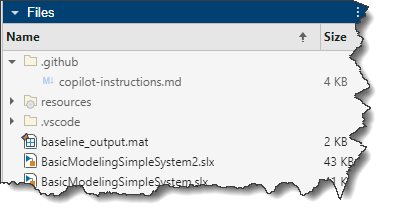

By the way, did you know that the MATLAB Editor is now able to display markdown files?

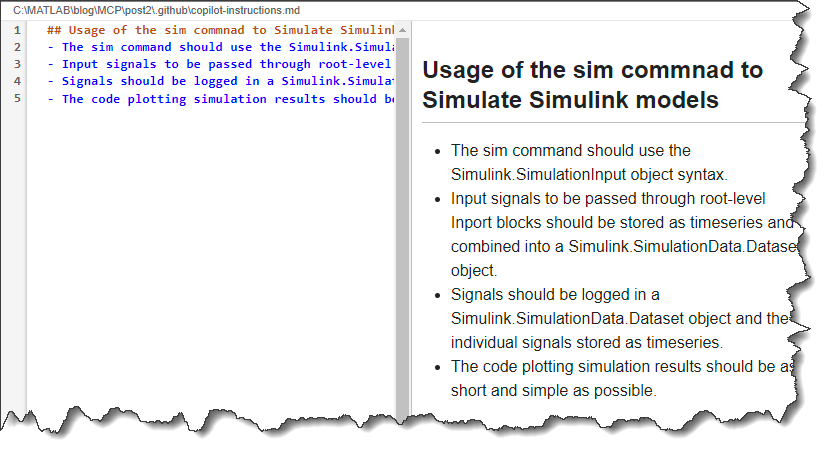

I typed my request in the GitHub Copilot chat, and it immediately created a first version of the script stepSim.m.

The generated code is not exactly what I want, but it's closer than the first attempt in my previous post.

% Model name
modelName = 'BasicModelingSimpleSystem';

% Load the model
load_system(modelName);

% Get the stop time from model
stopTime = str2double(get_param(modelName, 'StopTime'));

% Create time vector for step input signal
t = linspace(0, stopTime, 1000);
F_data = ones(size(t));

% Create step input as timeseries
F = timeseries(F_data, t);

% Create input dataset
simInput = Simulink.SimulationInput(modelName);
simInput = simInput.setExternalInput(F);

% Simulate the model
simOut = sim(simInput);

% Extract logged signals and plot 'x'
x_signal = simOut.logsout.getElement('x');
figure('Name', 'Step Response', 'NumberTitle', 'off');
plot(x_signal.Values.Time, x_signal.Values.Data, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('x');
title('Step Response of BasicModelingSimpleSystem');
grid on;

While this works, here are a few things I would like to tweak:

- There is no need to use `load_system` before simulating a model. The sim command will load the model if needed.

- I prefer to use `in` instead of `simInput` for the `Simulink.SimulationInput` object.

- I prefer to use `out` instead of `simOut` for the `Simulink.SimulationOutput` object.

- When plotting simulation results, I prefer to use the [`plot`](https://www.mathworks.com/help/matlab/ref/timeseries.plot.html) method of MATLAB `timeseries`, instead of extracting the time and data vectors.

Based on this result, I went through a series of iterations, adding more and more specific rules.

In the end, I came up with this set of rules: [copilot-instructions.md](https://github.com/simulink/blog/blob/main/2025_12_12_SimulinkAICodingRules/.github/copilot-instructions.md)

I repeated my original query. This time, the generated code is exactly what I was hoping for:

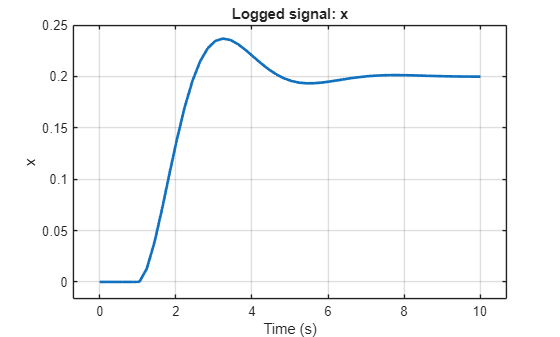

% Simulation end time (seconds)
tEnd = 10;

% Create a step timeseries: 0 for t < 1, 1 for t >= 1
t = linspace(0, tEnd, 1001)';
u = double(t >= 1);
stepTS = timeseries(u, t);

% Package into a dataset for external input
ds = Simulink.SimulationData.Dataset;
ds{1} = stepTS;

% Create SimulationInput using the model name (Simulink will load the model automatically)
in = Simulink.SimulationInput('BasicModelingSimpleSystem');
in = in.setModelParameter('StopTime', num2str(tEnd));
in = in.setExternalInput(ds);


% Run simulation
out = sim(in);

% Plot the logged signal 'x'
plot(out.logsout.get('x').Values);
title('Logged signal: x');
xlabel('Time (s)');
grid on;

Now that I have that working, let's keep exploring.

## MATLAB Test Class

For my next experiment, I tried creating a [MATLAB-Based Simulink Test](https://www.mathworks.com/help/sltest/ug/test-models-using-matlab-based-simulink-tests.html):

I was pretty happy with the results. It created 3 files:

- A script to generate and save the baseline

- A MAT-file containing the baseline results

- The requested MATLAB Test class

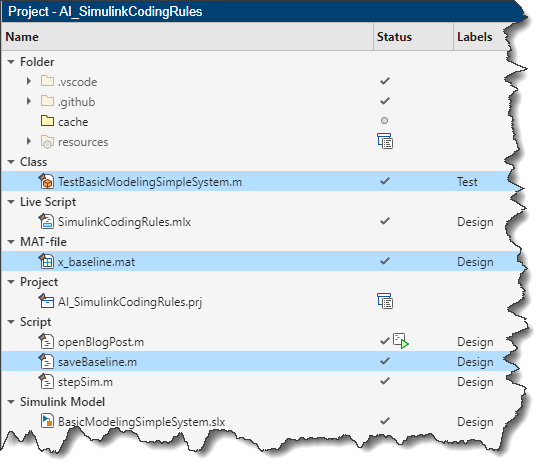

Here is what the MATLAB Test class looks like. It's simple and follows my coding rules.

I could add more rules to refine this test class, but I think this will be enough for today.

## Now it's your turn

What kind of Simulink AI Coding Rules would you like to see? Which AI coding assistant is your favorite? Let us know in the comments below.